%Least square approximation for linear functon
%Enter x and y in array form
% 𝑦 = 𝑎0 + 𝑎1*x:We will get a0 and a1 though least square approximation ans=r^2 =(Em-Else)/Else where 𝐸lse =∑(𝑦𝑖 − 𝑎1∗𝑥𝑖 − 𝑎0)^2 and  𝐸m = ∑(𝑦𝑖 − 𝑦̅)^2 where 𝑦̅ =∑ 𝑦𝑖/𝑛  and 𝑖=1 to n
%coefficient of determination, 𝑟^2 is defined as the relative error between 𝐸m and 𝐸lse
x=[1 2 3 4 5 6 7 8 9 10];
y=[1.3 3.5 4.2 5 7 8.8 10.1 12.5 13 15.6];
n=length(x);
format long
a1=(n*sum(x.*y)-sum(x)*sum(y))/(n*sum(x.^2)-(sum(x)).^2);
a0=sum(y)/n-a1*sum(x)/n;
r=(n*sum(x.*y)-sum(x)*sum(y))/((sqrt(n*sum(x.^2)-(sum(x))^2))*(sqrt(n*sum(y.^2)-(sum(y))^2)));
a1, a0

a1 =    1.538181818181819


a0 =   -0.360000000000005


r^2;

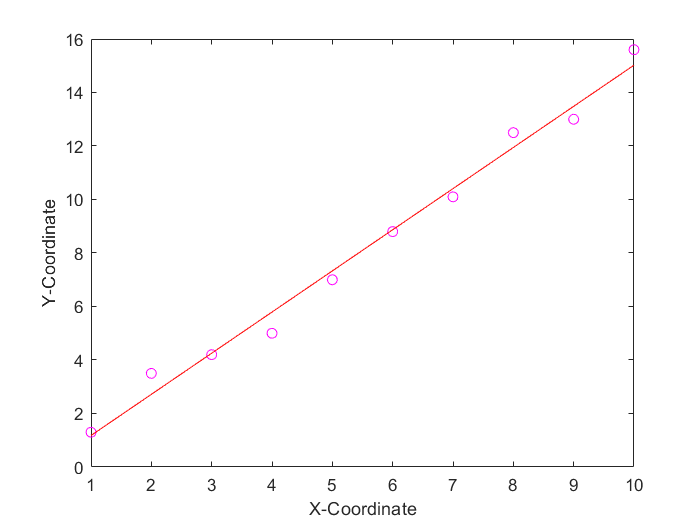

%plotting section
plot(x,y,"mo")
f= a0 + a1*x;
xlabel('X-Coordinate')
ylabel('Y-Coordinate')
hold on
plot(x,f,"-r")
hold off


%xlim([min(x) max(x)+2])
%ylim([min(y)-2 max(y)+2])